# **Lab 5**

## **Bode Plot**

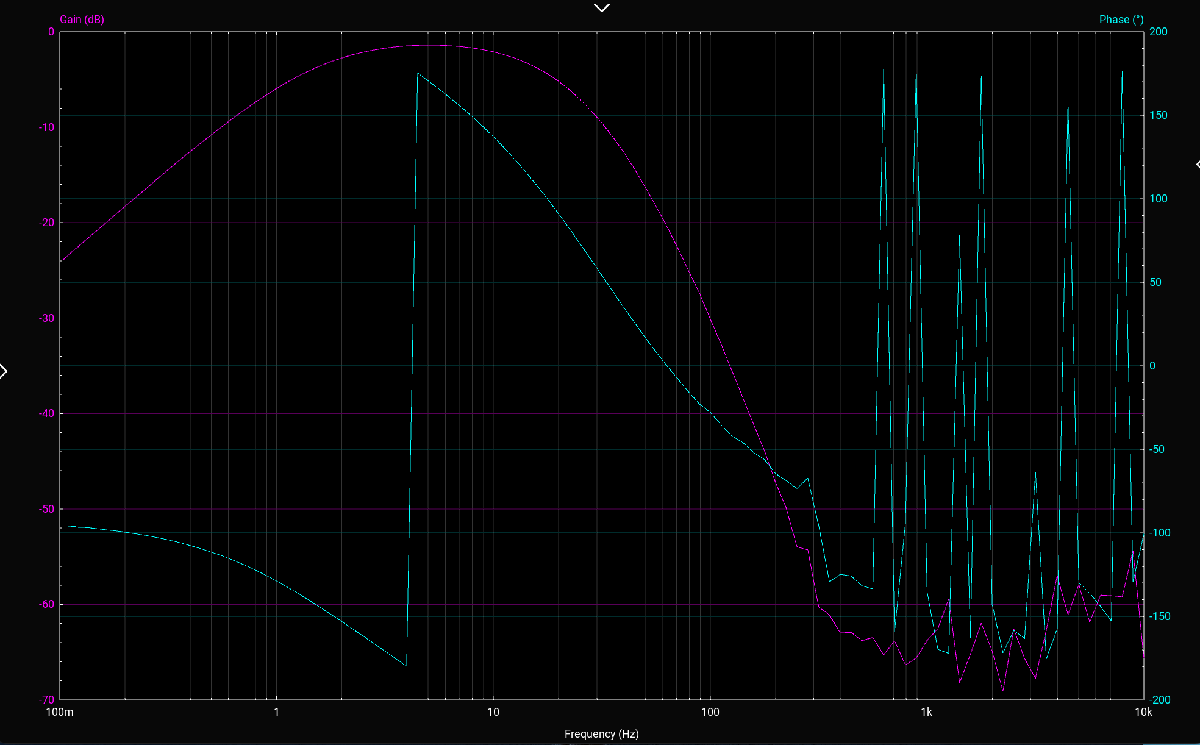

The bode plot (Gain (dB) vs. Frequency (Hz)) used to measure the amplitude of the EKG circuit.

## **EKG Trace**

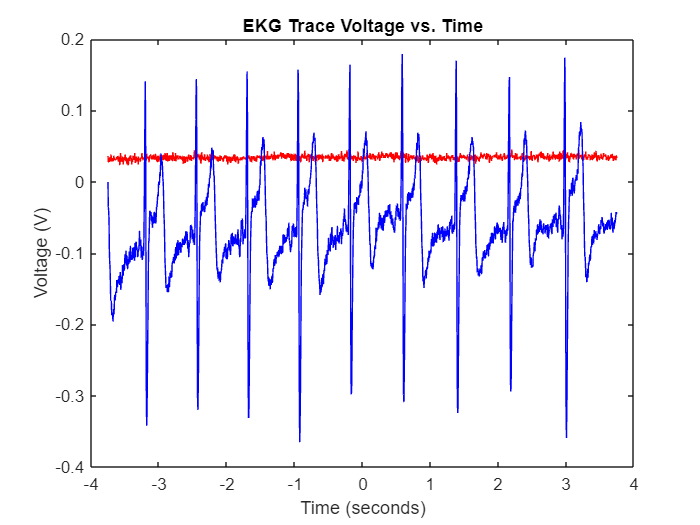

%take in data from csv file
tname='lab5data.csv'; % <-input your data file's name! test2.csv was exported from O-scope software with a line of headers
datatable  = readtable(tname);%makes data table with headers

%interpret data as times and voltages
time1  = datatable.t1; % stores the t1 column of data in a variable called time1 
V1    = datatable.ch1; % stores the ch1 column of data in a variable called V1   
time2    = datatable.t2; %stores the t2 column of data in a variable called time2 
V2 = datatable.ch2; %stores the ch2 column of data in a variable called V2   

%plot (you can change this section to suit your plotting needs!)
plot(time1,V1, 'r')
hold on
plot(time2, V2, 'b')%plots first channel
xlabel('Time (seconds)'); % add x axis label 
ylabel('Voltage (V)'); % add y axis label 
title('EKG Trace Voltage vs. Time')

A graph of the EKG trace taken by place electrodes on the wrist.

## **Circuit**

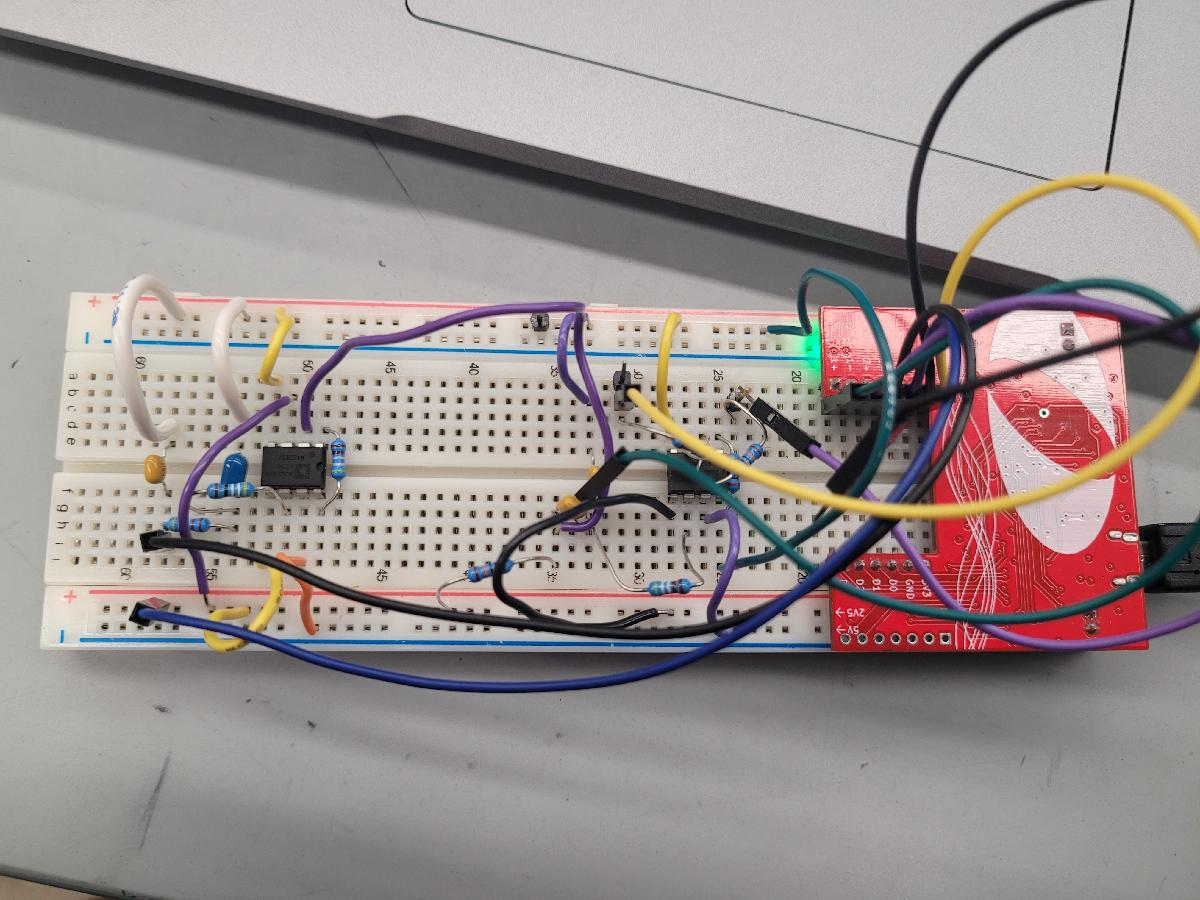

## **How Does the Circuit Function?**

The EKG circuit is made up of two stages of filtering and amplification. The first stage uses a AD623 amplifier chip with a passive band-pass filter that filters out both high and low frequencies. The second stage has 2 RC circuits in series which form 2 low-pass filters. The characteristic frequencies of the circuit range from about 1 Hz to 20 Hz. For the first stage, the gain is set to 51, and in the second, it's 21, causing the output voltage to be amplified by a factor of about 1000. This ensures that the EKG signal is effectively captured while minimizing noise interference. 